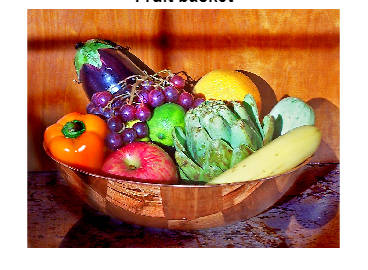

clear all

I = imread('Fruits.jpg'); % Read image file
figure, imshow(I) % Display original image
title('Fruit basket');

IRed = I(:,:,1); % Extract red layer
IGreen = I(:, :, 2); % Extract green layer
IBlue = I(:, :, 3); % Extract blue layer
Ithreshold = zeros(783,1024);  % Begin binary image


## Bounding Box Apple

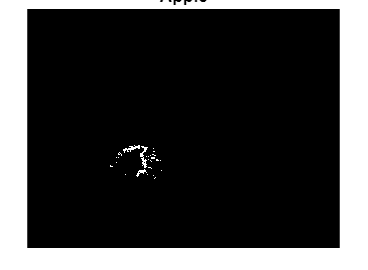


for i = 1:783
    for j = 1:1024
        % Detect pixels that obey threshold (to find apple)
        if IRed(i,j) > 233 && IGreen(i, j) < 50 && IBlue(i,j) > 13
            Ithreshold(i,j) = 255; % Convert to white pixel
        else
            Ithreshold(i,j) = 0; % Conver to black pixel
        end
    end
end

Ithreshold = uint8(Ithreshold); % Convert the binary image to uint8
figure, imshow(Ithreshold) % Display the thresholded image
title('Apple')

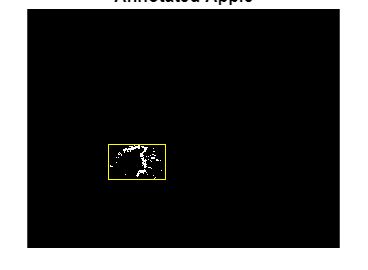


[row, col] = find(Ithreshold == 255); % Find white pixel positions

if ~isempty(row)
    % Determine bounding box limits
    minRow = min(row); % Top-most pixel
    maxRow = max(row); % Bottom-most pixel
    minCol = min(col); % Left-most pixel
    maxCol = max(col); % Right-most pixel
    
    % Create bounding box coordinates
    boundingboxA = [minCol, minRow, maxCol - minCol + 1, maxRow - minRow + 1];
end

annotatedImageA = insertShape(Ithreshold,"rectangle",boundingboxA,"LineWidth",3);% Insert bounding box
imshow(annotatedImageA)% Display image with bounding box
hold on
title('Annotated Apple')

## Centroid Apple

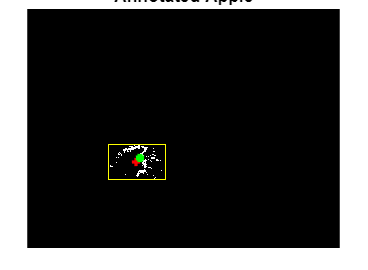

% Mid-point
midpointRowA = (maxRow + minRow)/2;  % Compute midpoint row
midpointColA = (maxCol + minCol)/2;  % Compute midpoint column
plot(midpointColA, midpointRowA,'r+', 'MarkerSize', 5, 'LineWidth', 2)

% Moment method
M10 = 0;  % Initialize moment
M01 = 0;  % Initialize moment

sum_of_pixels = sum(Ithreshold(:));  % Sum of all white pixels
M00 = sum_of_pixels/255;  % Normalize sum

Ithreshold = double(Ithreshold);  % Convert binary image to double

for i = 1:783
    for j = 1:1024
        M10 = M10 + j*(Ithreshold(i,j)/255);  % Calculate M10
        M01 = M01 + i*(Ithreshold(i,j)/255);  % Calculate M01
    end
end

X_centroidA = M10/M00;  % X-coordinate of the centroid
Y_centroidA = M01/M00;  % Y-coordinate of the centroid
plot(X_centroidA, Y_centroidA,'r+', 'MarkerSize', 5, 'LineWidth', 3,'Color', "g")

## Bounding Box Lemon

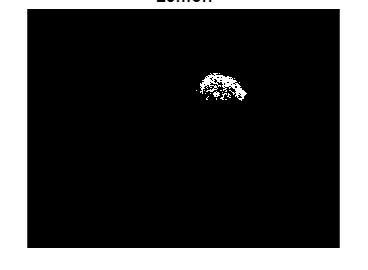

for i = 1:783
    for j = 1:1024
        % Detect pixels corresponding to the lemon
        if IRed(i,j) > 247 && IGreen(i, j) > 216 && IBlue(i, j) < 100
            Ithreshold(i,j) = 255;  % Convert to white pixel
        else
            Ithreshold(i,j) = 0;  % Convert to black pixel
        end
    end
end

Ithreshold = uint8(Ithreshold);  % Convert binary image to uint8
figure, imshow(Ithreshold)  % Display thresholded lemon image
title('Lemon')

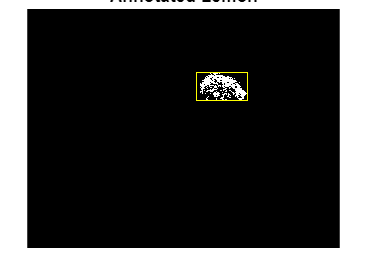


[row, col] = find(Ithreshold == 255);  % Find white pixel positions

if ~isempty(row)
    % Determine bounding box limits
    minRow = min(row);  % Top-most pixel
    maxRow = max(row);  % Bottom-most pixel
    minCol = min(col);  % Left-most pixel
    maxCol = max(col);  % Right-most pixel
    
    % Create bounding box coordinates
    boundingboxL = [minCol, minRow, maxCol - minCol + 1, maxRow - minRow + 1];
end

annotatedImageL = insertShape(Ithreshold,"rectangle",boundingboxL,"LineWidth",3);  % Insert bounding box
imshow(annotatedImageL)  % Display annotated lemon image
hold on
title('Annotated Lemon')

## Centroid Lemon

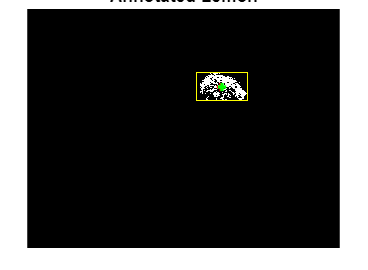

% Mid-point
midpointRowL = (maxRow + minRow)/2;  % Compute midpoint row
midpointColL = (maxCol + minCol)/2;  % Compute midpoint column
plot(midpointColL, midpointRowL,'r+', 'MarkerSize', 5, 'LineWidth', 2)

% Moment method to calculate the centroid
M10 = 0;  % Initialize moment
M01 = 0;  % Initialize moment

sum_of_pixels = sum(Ithreshold(:));  % Sum of all white pixels
M00 = sum_of_pixels/255;  % Normalize sum

Ithreshold = double(Ithreshold);  % Convert binary image to double

for i = 1:783
    for j = 1:1024
        M10 = M10 + j*(Ithreshold(i,j)/255);  % Calculate M10
        M01 = M01 + i*(Ithreshold(i,j)/255);  % Calculate M01
    end
end

X_centroidL = M10/M00;  % X-coordinate of the centroid
Y_centroidL = M01/M00;  % Y-coordinate of the centroid
plot(X_centroidL, Y_centroidL,'r+', 'MarkerSize', 5, 'LineWidth', 2,'Color', "g")

## Bounding Box Capsicum

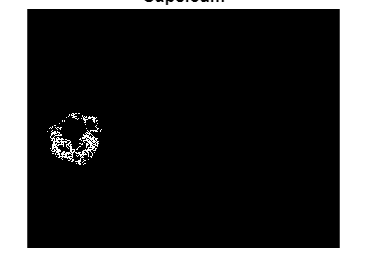

for i = 1:783
    for j = 1:1024
        % Detect pixels corresponding to the capsicum
        if IRed(i,j) > 254 && IGreen(i, j) < 150 && IBlue(i, j) < 10
            Ithreshold(i,j) = 255;  % Convert to white pixel
        else
            Ithreshold(i,j) = 0;  % Convert to black pixel
        end
    end
end

Ithreshold = uint8(Ithreshold);
figure, imshow(Ithreshold)  % Display thresholded capsicum image
title('Capsicum')

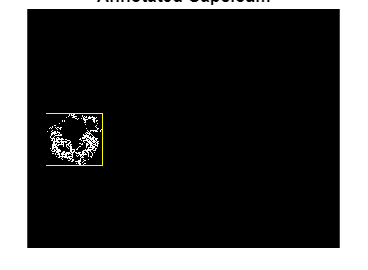


[row, col] = find(Ithreshold == 255);  % Find white pixel positions

if ~isempty(row)
    % Determine bounding box limits
    minRow = min(row);  % Top-most pixel
    maxRow = max(row);  % Bottom-most pixel
    minCol = min(col);  % Left-most pixel
    maxCol = max(col);  % Right-most pixel
    
    % Create bounding box coordinates
    boundingboxC = [minCol, minRow, maxCol - minCol + 1, maxRow - minRow + 1];
end

annotatedImageC = insertShape(Ithreshold,"rectangle",boundingboxC,"LineWidth",3);
imshow(annotatedImageC)  % Display annotated capsicum image
hold on
title('Annotated Capsicum')

## Centroid Capsicum

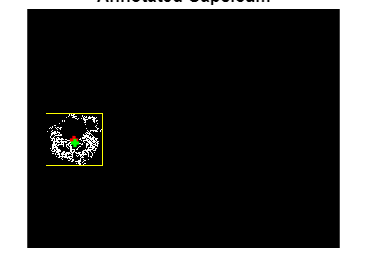

% Mid-point
midpointRowC = (maxRow + minRow)/2;  % Compute midpoint row
midpointColC = (maxCol + minCol)/2;  % Compute midpoint column
plot(midpointColC, midpointRowC,'r+', 'MarkerSize', 5, 'LineWidth', 2)

% Moment method to calculate the centroid
M10 = 0;  % Initialize moment
M01 = 0;  % Initialize moment

sum_of_pixels = sum(Ithreshold(:));  % Sum of all white pixels
M00 = sum_of_pixels/255;  % Normalize sum

Ithreshold = double(Ithreshold);  % Convert binary image to double

for i = 1:783
    for j = 1:1024
        M10 = M10 + j*(Ithreshold(i,j)/255);  % Calculate M10
        M01 = M01 + i*(Ithreshold(i,j)/255);  % Calculate M01
    end
end

X_centroidC = M10/M00;  % X-coordinate of the centroid
Y_centroidC = M01/M00;  % Y-coordinate of the centroid
plot(X_centroidC, Y_centroidC,'r+', 'MarkerSize', 5, 'LineWidth', 2,'Color', "g")

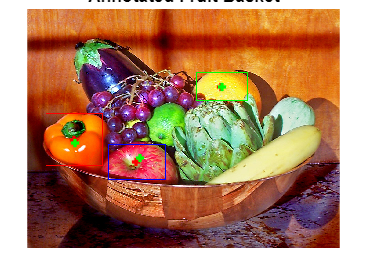

annotatedImage = insertShape(I,"rectangle",boundingboxA,"LineWidth",3, "ShapeColor","blue");
annotatedImage2 = insertShape(annotatedImage,"rectangle",boundingboxL,"LineWidth",3, "ShapeColor","green");
annotatedImage3 = insertShape(annotatedImage2,"rectangle",boundingboxC,"LineWidth",3, "ShapeColor","red");
title('Annotated Fruit Basket')
imshow(annotatedImage3) % Display all the bounding boxes into the original image
hold on
% Input all the mid-points in the original image
plot(midpointColA, midpointRowA,'r+', 'MarkerSize', 5, 'LineWidth', 2)
plot(midpointColL, midpointRowL,'r+', 'MarkerSize', 5, 'LineWidth', 2)
plot(midpointColC, midpointRowC,'r+', 'MarkerSize', 5, 'LineWidth', 2)
% Input all the centroids in the original image
plot(X_centroidA, Y_centroidA,'r+', 'MarkerSize', 5, 'LineWidth', 2,'Color', "g")
plot(X_centroidL, Y_centroidL,'r+', 'MarkerSize', 5, 'LineWidth', 2,'Color', "g")
plot(X_centroidC, Y_centroidC,'r+', 'MarkerSize', 5, 'LineWidth', 2,'Color', "g")